clear;
clear clc;
% PHYS 434
% LAB 4
% Jin Kyoung Lee

## Problem 1

h5disp("LAB/gammaray_lab4.h5")

HDF5 gammaray_lab4.h5 
Group '/' 
    Dataset 'data' 
        Size:  25920001x4
        MaxSize:  25920001x4
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


gammarayData = h5read("LAB/gammaray_lab4.h5",'/data');
% gammaray_lab4.h5: reading of the number of particles detected every 100
% milliseconds (gamma-ray satellite has approx. 90 min. orbit)
% Columns:
% time(in gps seconds);
% solar phase(deg) showing the position of the sun relative to the orbit;
% Earth longitude(deg): giving the position of the spacecraft relative to
% the ground;
% particle counts
% Rows: # of samples
gammarayData(1,:)

ans =    940680016         315          45          10


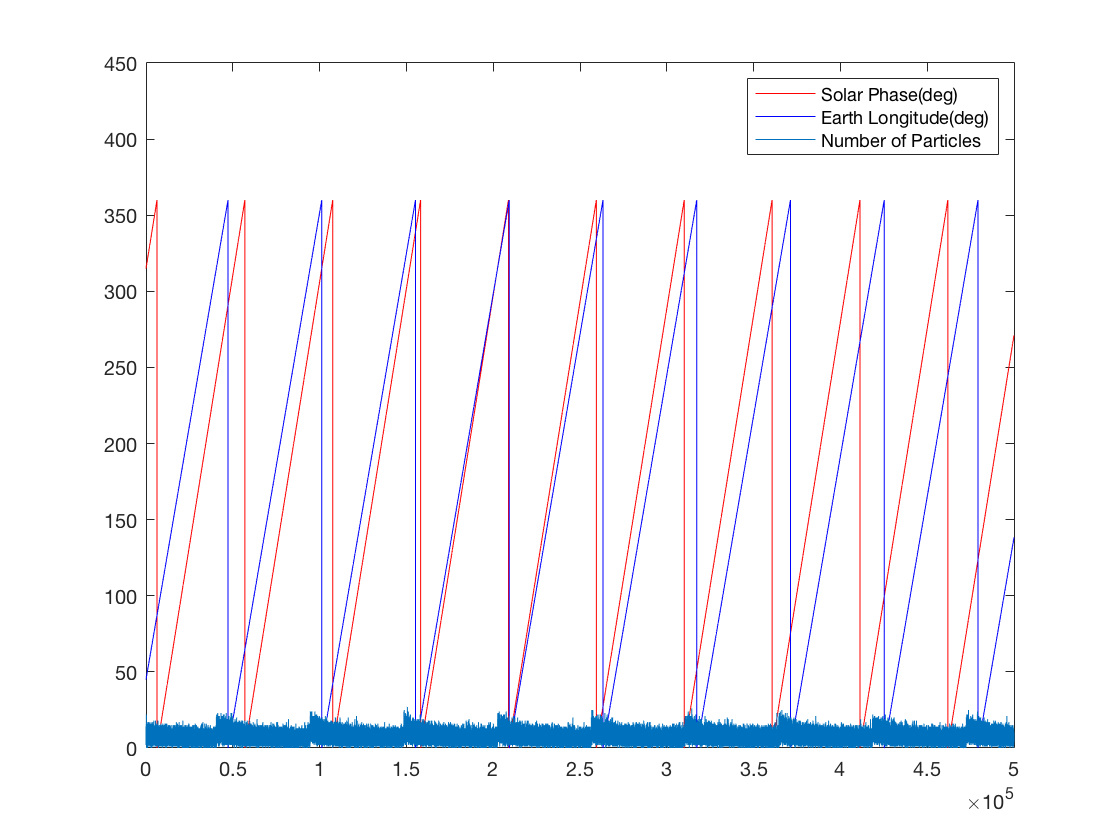

% Time (sec) | Phase (deg) | Longitude (deg) | # of particle

% 1)
% Plot
phase = gammarayData(1:500000,2);
plot(phase,"Red") % Solar phase plot
hold on
longitude = gammarayData(1:500000,3);
plot(longitude,"Blue") % Earth longitude plot
numOfParticle = gammarayData(1:500000,4);
plot(numOfParticle) % Number of particle plot
ylim([0,450]);
legend('Solar Phase(deg)','Earth Longitude(deg)','Number of Particles')
hold off

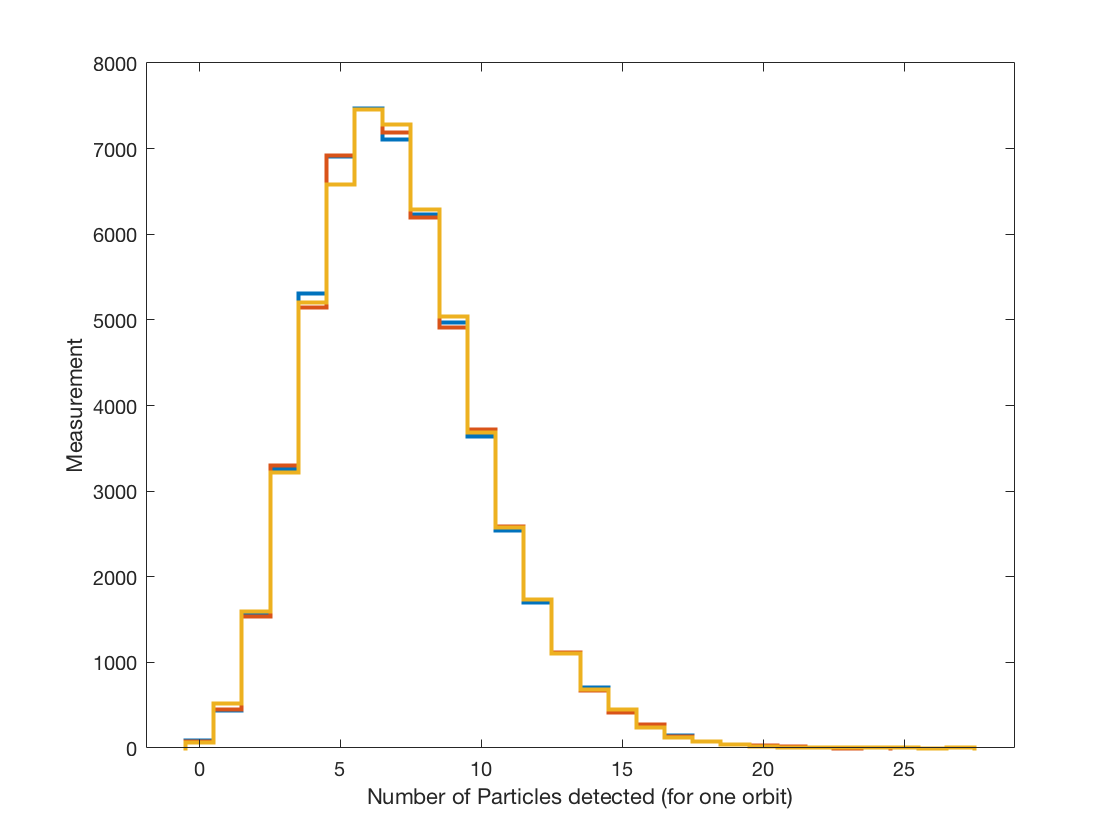

% 90 min = 5400000 millisec, and the satellite takes reading every 100
% milliseconds, therefore, 54000 readings/orbit. Therefore, if we make
% histogram for the number of particles detected every 54000 readings, we
% will be able to see the distribution for the background.

numOfParticleHist = gammarayData(1:54000,4).'; % 1st orbit
%subplot(1,2,1);
histogram(numOfParticleHist,'DisplayStyle','Stairs','LineWidth',2)
hold on
numOfParticleHist1 = gammarayData(54001:108000,4).'; % 2nd orbit
histogram(numOfParticleHist1,'DisplayStyle','Stairs','LineWidth',2)
numOfParticleHist2 = gammarayData(108001:162000,4).'; % 3nd orbit
histogram(numOfParticleHist2,'DisplayStyle','Stairs','LineWidth',2)
xlabel('Number of Particles detected (for one orbit)')
ylabel('Measurement')
hold off

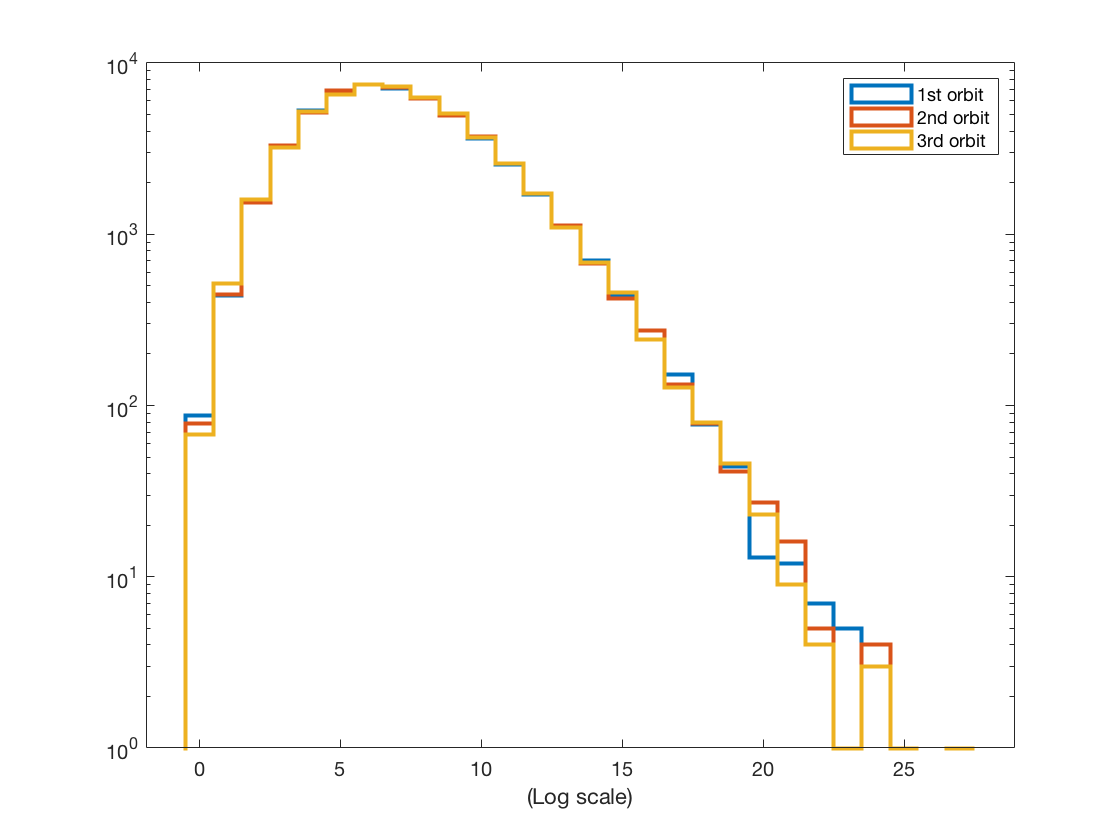

%subplot(1,2,2);
histogram(numOfParticleHist,'DisplayStyle','Stairs','LineWidth',2)
hold on
histogram(numOfParticleHist1,'DisplayStyle','Stairs','LineWidth',2)
histogram(numOfParticleHist2,'DisplayStyle','Stairs','LineWidth',2)
set(gca,'YScale','log')
xlabel('(Log scale)')
legend('1st orbit','2nd orbit','3rd orbit')
hold off

% By making histogram for number of particles detected for one orbit, it is
% observed that the background distribution follows Poisson distribution.

## Problem 2

h5disp("LAB/images.h5")

HDF5 images.h5 
Group '/' 
    Dataset 'image1' 
        Size:  200x200
        MaxSize:  200x200
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000
    Dataset 'imagestack' 
        Size:  10x200x200
        MaxSize:  10x200x200
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


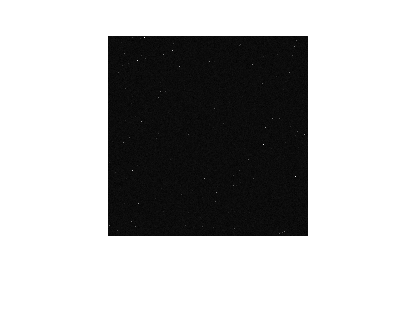

image1 = h5read("Lab/images.h5",'/image1');
imagestack = h5read("LAB/images.h5",'/imagestack');
I = mat2gray(image1);
imshow(I)

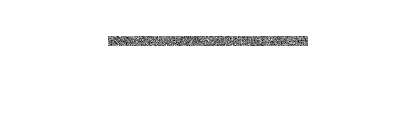

I2 = mat2gray(imagestack(:,:,1));
imshow(I2)

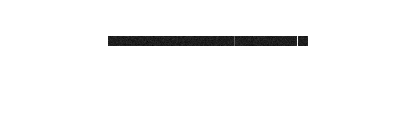

I2 = mat2gray(imagestack(:,:,2));
imshow(I2)

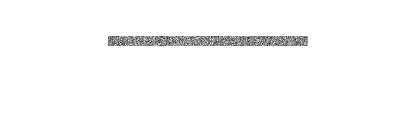

I2 = mat2gray(imagestack(:,:,3));
imshow(I2)

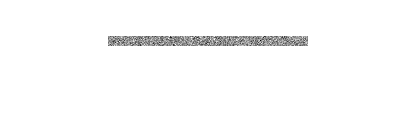

I2 = mat2gray(imagestack(:,:,4));
imshow(I2)

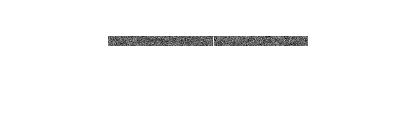

I2 = mat2gray(imagestack(:,:,5));
imshow(I2)

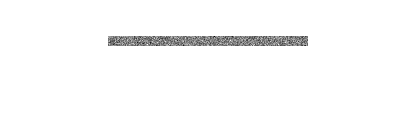

I2 = mat2gray(imagestack(:,:,6));
imshow(I2)